# Detecting Malaria with CNN

## How simple can it be?

Dataset: [https://ceb.nlm.nih.gov/repositories/malaria-datasets/](https://ceb.nlm.nih.gov/repositories/malaria-datasets/) 

clr
filepath = strcat(pwd, "\data_edited");
imds = imageDatastore(filepath, 'IncludeSubfolders',true,'LabelSource','foldernames');

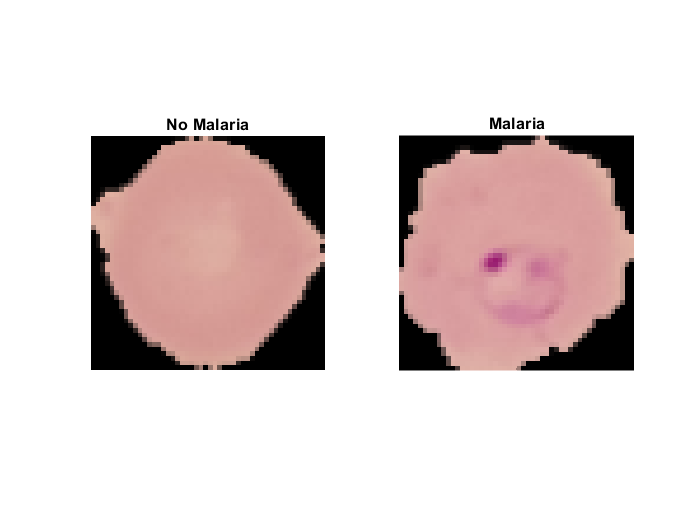

labelCount = countEachLabel(imds);
subplot(1, 2, 1)
imshow(imds.Files{1})
title("No Malaria")


subplot(1, 2, 2)
imshow(imds.Files{13780})
title("Malaria")

disp(labelCount)

    Label    Count
    _____    _____
      0      13779
      1      13779


imSize = size(imread(imds.Files{1}));
numberOfLabels = length(unique(imds.Labels));

trainingSize = 0.75;
rng(1)
[trainData, testData] = splitEachLabel(imds, trainingSize, 'randomize');

% Using the deep network designer to design my deep network
deepNetworkDesigner

load("network_layers.mat")

% Training  Options
options = trainingOptions('sgdm', 'MaxEpochs', 5, 'InitialLearnRate', 0.001);
CNN = trainNetwork(trainData, layers, options);
% save('malariaCNN.mat', 'CNN')

CNN = load("malariaCNN.mat");
CNN = CNN.CNN;

## Result

close
yTest = classify(CNN, testData);

Undefined function or variable 'CNN'.

tTest = testData.Labels;
accuracy = sum(yTest == tTest)/(numel(tTest));
disp(accuracy)

## plot result

close all
labels = ["No Malaria", "Malaria"];
index = randperm(6890, 12*4);
figure
plotCount = 1;
text(100, 20,sprintf("accuracy = %0.2f%%", accuracy*100));
for ii = 1:numel(index)
    I = readimage(testData, index(ii));
    pred = (yTest(index(ii)));
    label = tTest(index(ii));
    if label == pred
        color = 'g';
    else
        color = 'r';
    end
    
    subplot(3, 4, plotCount)
    imshow(I)
    title(sprintf("pred: %s (%s)", labels{pred}, labels{label}), "Color", color)
    plotCount = plotCount + 1;
    if mod(ii, 12) == 0
        pause(1.3)
        clf
        plotCount = 1;
    end
end
figure
plotconfusion(tTest, yTest);

xlabel(sprintf("accuracy = %0.2f%%", accuracy*100))